# RBE502: Final exam

Nathiel Goldfarb

## Problem 1.a

    To solve for the equilibra points, both equations are set to 0 and solved simultaneously. 


$$0 = -2x -y-x^2\\
0 = x+ y \rightarrow x= -y\\
y =  \pm 1\\
x = -y$$


## Problem 1.b

    To see of the points are stable the Jacobian of the system is found.

   
$$J = \det{ \pmatrix{ -(2 + 2x) & -1 \cr 1 & 1 }  } = - 2 -2x +1$$


   
$$J(-1)  = 1 \neq 0\\
J(1)  = -3 \neq 0$$


Since the Jacobian is not 0 at the equilibra points, the system is unstable.

## Problem 2.a

    As above we set all the functions to 0.

                                                                                                                $ \pmatrix{ -x + yx + zcos(x) \cr -x^2 \cr -xcos(x) }  } $=  $\pmatrix{ 0 \cr 0 \cr 0}$

    By inspection we find that 


$$
x  = 0\\
z = 0\\
y \in \Re$$


## Problem 2.b

Taking the deritive of the  Lyapunov function yeilds

   
$$\dot{V} = 2x\dot{x}+2y\dot{y}+2z\dot{z}$$


pluging   $x=y=z=0$ to $\dot{V}$ 

##  
$$\dot{V} \leq 0$$


## Problem 3.a

syms x1 x2 x3 x4  a1 a2 u1 u2

f = [ x3;...
      x4;...
    -(3*x1*x2+x2^2);
    -x4*cos(x1)-3*(x1-x2)]  

$$f = \left(\begin{array}{c} x_{3}\\ x_{4}\\ -{x_{2}}^{2}-3\,x_{1}\,x_{2}\\ 3\,x_{2}-3\,x_{1}-x_{4}\,\cos\left(x_{1}\right) \end{array}\right)$$

  
 g = [0 0;...
      0 0;
      1 x2;...
      -3*x3*cos(x1)^2 1]

$$g = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & x_{2}\\ -3\,x_{3}\,{\cos\left(x_{1}\right)}^{2} & 1 \end{array}\right)$$

## Problem 3.b

f1 = -(3*x1*x2+x2^2) + u1 + x2*u2 - a1

$$f1 = u_{1}-a_{1}+u_{2}\,x_{2}-3\,x_{1}\,x_{2}-{x_{2}}^{2}$$

f2 = -x4*cos(x1)-3*(x1-x2) -u1*3*x3*cos(x1)^2 + u2 - a2

$$f2 = -3\,u_{1}\,x_{3}\,{\cos\left(x_{1}\right)}^{2}-x_{4}\,\cos\left(x_{1}\right)-a_{2}+u_{2}-3\,x_{1}+3\,x_{2}$$


 
F = [ f1==0, f2==0];
U = solve( F, [u1,u2]);


The value of u1 is 

U.u1

$$ans = \frac{a_{1}-a_{2}\,x_{2}+4\,{x_{2}}^{2}-x_{2}\,x_{4}\,\cos\left(x_{1}\right)}{3\,x_{2}\,x_{3}\,{\cos\left(x_{1}\right)}^{2}+1}$$

The value of u1 is

U.u2

$$ans = \frac{3\,x_{3}\,{x_{2}}^{2}\,{\cos\left(x_{1}\right)}^{2}+9\,x_{1}\,x_{3}\,x_{2}\,{\cos\left(x_{1}\right)}^{2}-3\,x_{2}+3\,a_{1}\,x_{3}\,{\cos\left(x_{1}\right)}^{2}+x_{4}\,\cos\left(x_{1}\right)+a_{2}+3\,x_{1}}{3\,x_{2}\,x_{3}\,{\cos\left(x_{1}\right)}^{2}+1}$$


K = simplify( g*[U.u1;U.u2]+ f)

$$K = \left(\begin{array}{c} x_{3}\\ x_{4}\\ a_{1}\\ a_{2} \end{array}\right)$$

## Problem 4.a

clear all
syms x1 x2 u

f = [  x2; -sin(x1)]

$$f = \left(\begin{array}{c} x_{2}\\ -\sin\left(x_{1}\right) \end{array}\right)$$

g = [0;1]

g =      0
     1


## Problem 4.b

using the lie bracket...

L = jacobian(g,[x1,x2])*f - jacobian(f,[x1,x2])*g

$$L = \left(\begin{array}{c} -1\\ 0 \end{array}\right)$$

Yes because this system can be driven to this point

## Problem 4.c


$$\dot{z} = Az+Bv\\\
$$



$$\pmatrix{\dot{y} \cr \ddot{y} } = Az+B \ddot{y}\\
 = A\pmatrix{ y \cr y } +B \ddot{y}\\
\pmatrix{\dot{z}_1 \cr  \dot{z}_2 } = A\pmatrix{z_1 \cr  z_2 }+B v\\$$



$$u =  v + sin(z_1)$$


By inspection the A and B matrixs are

## Problem 4.d

To eliminate u from the equaion a feed back grain is set up, which get a equation for v.


$$u = -sin(z_1) + v \\
-Kz = -sin(z_1) + v \\
v = - ( Kz + sin(z_1))   $$


This sets up the ODE45. 

[t,z] = ode45(@vdp1,[0 10],[5; 5])

t =          0
    0.0025
    0.0051
    0.0076
    0.0101
    0.0228
    0.0355
    0.0482
    0.0609
    0.0795


z =     5.0000    5.0000
    5.0124    4.7518
    5.0241    4.5095
    5.0352    4.2730
    5.0458    4.0421
    5.0901    2.9680
    5.1216    2.0172
    5.1417    1.1766
    5.1518    0.4342
    5.1510   -0.5015


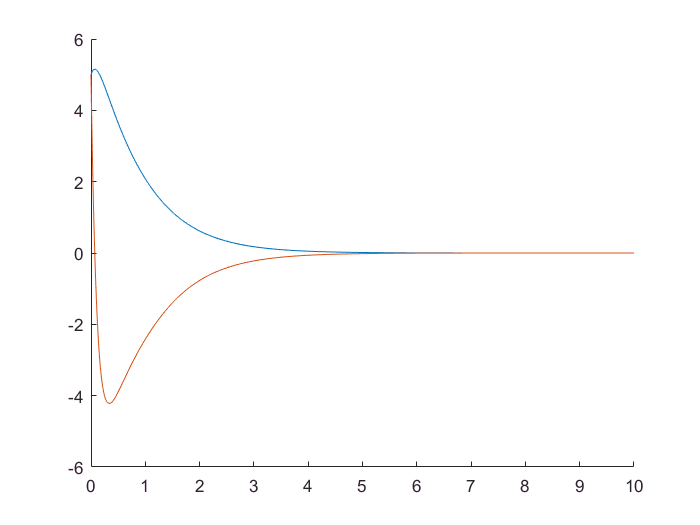


hold on 
plot(t, z(:,1));
plot(t, z(:,2));

function dydt = vdp1(t,z)
   
    A = [ 0 1;...
          0 0];
    B = [0;1];
    K = [ 10, 10];
    v =  -( K*z + sin(z(1)) );
    dydt = A*z + B*v;

end


